syms t
N_max = 60;
f = sqrt(1+t^2);
asimpt_coeff = zeros(1,N_max);

asimpt_coeff(1) = subs(f,0);
for k = 2:length(asimpt_coeff)
    asimpt_coeff(k) = subs(diff(f,k-1),0);
end

lambda    = [1:0.1:15];
result_as = zeros(length(lambda),N_max);
result_qa = zeros(1,length(lambda));

for i = 1:length(lambda)
    for j = 1:N_max
        result_as(i,j) = LaplasTransformAssimptoticSerias(asimpt_coeff(1:j), lambda(i));
    end
    
end

for i = 1:length(lambda)
    fun = @(t) sqrt(1+t.^2).*exp(-lambda(i).*t);
    result_qa(i) = quad(fun,0,50);
end


Вывод полученных результатов

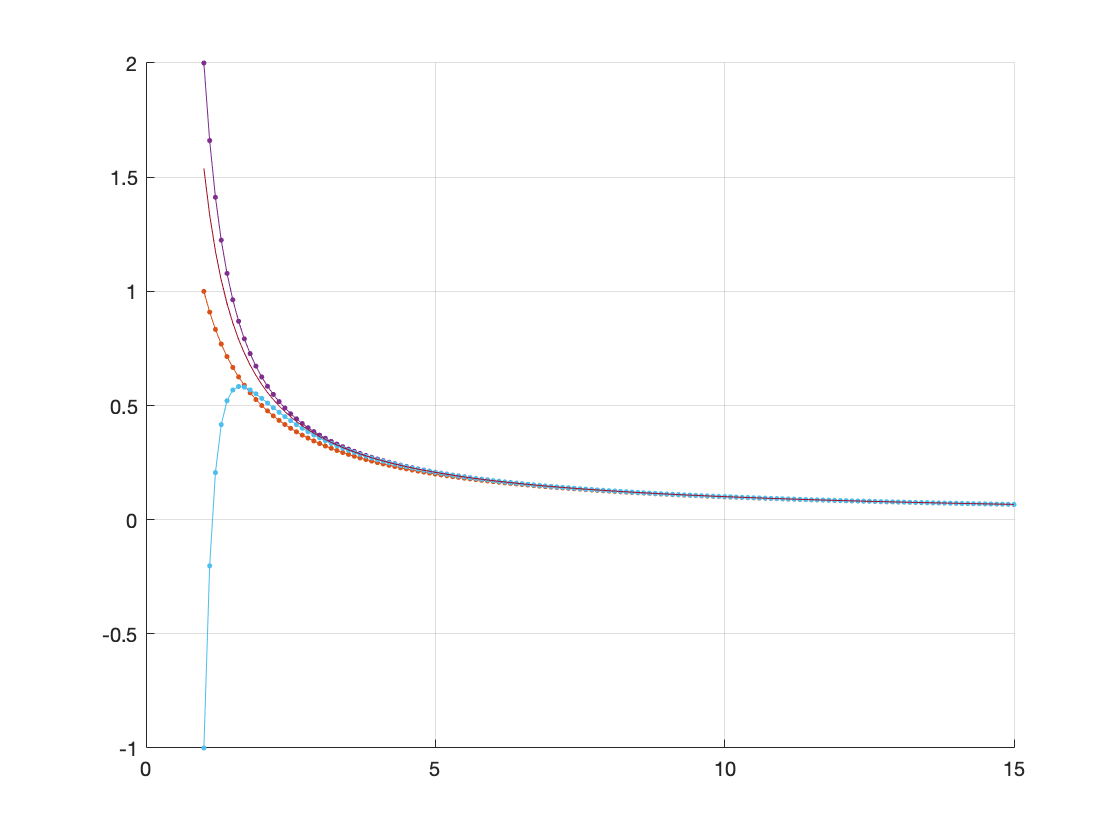

hold on; grid on;
plot(lambda, result_as(:,1),'.-')
plot(lambda, result_as(:,2),'.-')
plot(lambda, result_as(:,3),'.-')
plot(lambda, result_as(:,4),'.-')
plot(lambda, result_as(:,5),'.-')
plot(lambda, result_as(:,6),'.-')

plot(lambda,result_qa)

Вчисление для малых lambda

syms t
N_max = 15;
f = sqrt(1+t^2);
asimpt_coeff = zeros(1,N_max);

asimpt_coeff(1) = subs(f,0);
for k = 2:length(asimpt_coeff)
    asimpt_coeff(k) = subs(diff(f,k-1),0);
end

lambda    = [1,3,5,7];
result_as = zeros(length(lambda),N_max);
result_qa = zeros(1,length(lambda));

for i = 1:length(lambda)
    for j = 1:N_max
        result_as(i,j) = LaplasTransformAssimptoticSerias(asimpt_coeff(1:j), lambda(i));
    end
    
end

for i = 1:length(lambda)
    fun = @(t) sqrt(1+t.^2).*exp(-lambda(i).*t);
    result_qa(i) = quad(fun,0,50);
end

disp(lambda(1))

     1



result_qa(1)

ans = 1.5389

result_as(1,1:10)

ans =            1           1           2           2          -1          -1          44          44       -1531       -1531



disp(lambda(2))

     3



result_qa(2)

ans = 0.3641

result_as(2,:)

ans =     0.3333    0.3333    0.3704    0.3704    0.3580    0.3580    0.3786    0.3786    0.2986    0.2986    0.8587    0.8587   -5.3027   -5.3027   92.5952



disp(lambda(3))

     5



result_qa(3)

ans = 0.2073

result_as(3,:)

ans =     0.2000    0.2000    0.2080    0.2080    0.2070    0.2070    0.2076    0.2076    0.2068    0.2068    0.2088    0.2088    0.2008    0.2008    0.2468



disp(lambda(4))

     7



result_qa(4)

ans = 0.1456

result_as(4,:)

ans =     0.1429    0.1429    0.1458    0.1458    0.1456    0.1456    0.1456    0.1456    0.1456    0.1456    0.1457    0.1457    0.1456    0.1456    0.1459
